i = 1

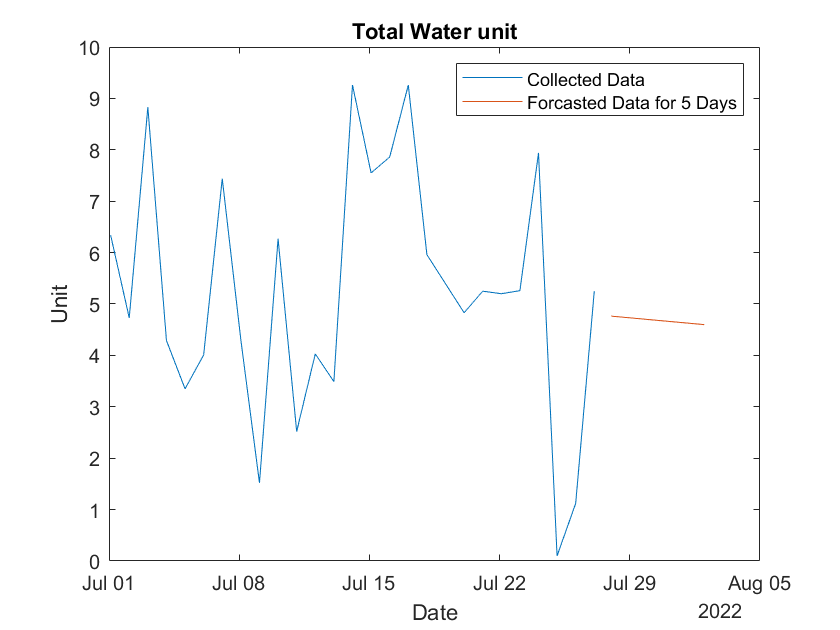

i = 2

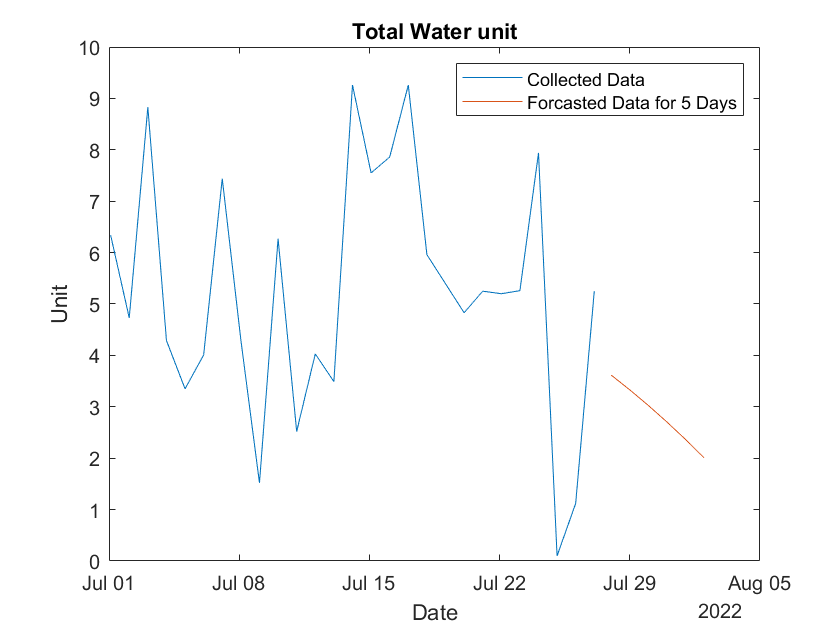

i = 3

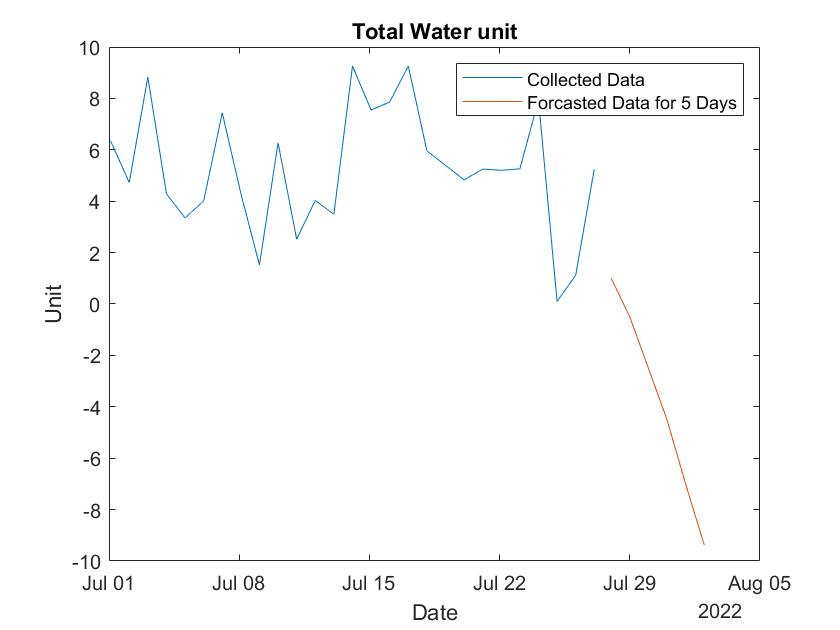

i = 4

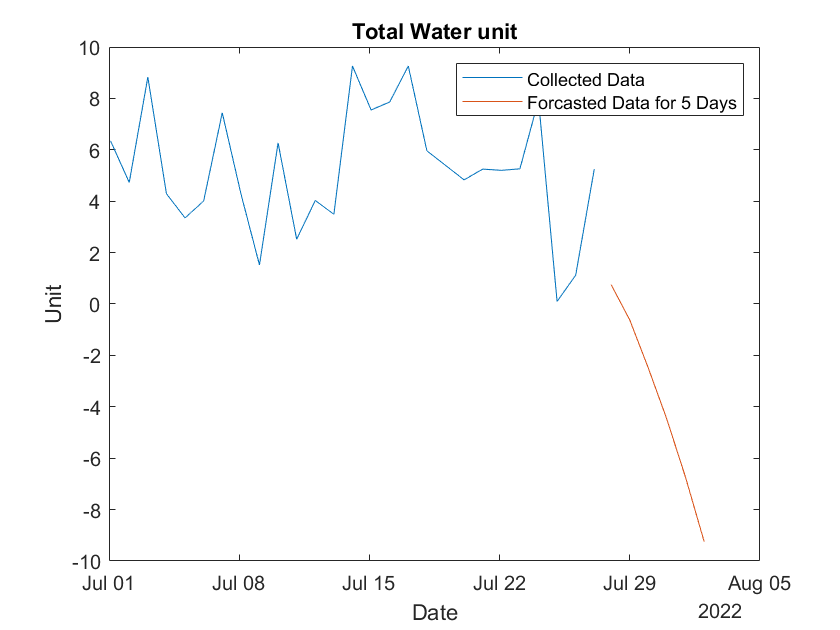

i = 5

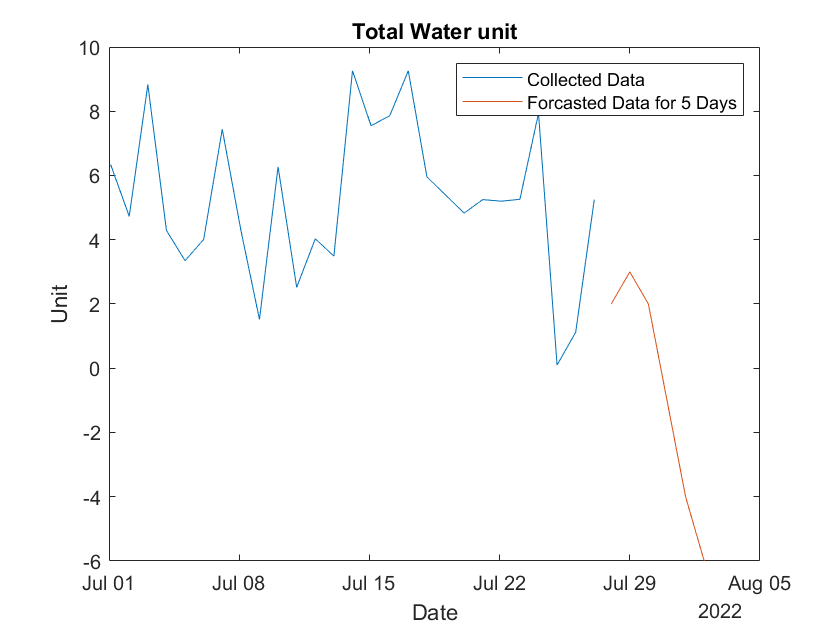

i = 6

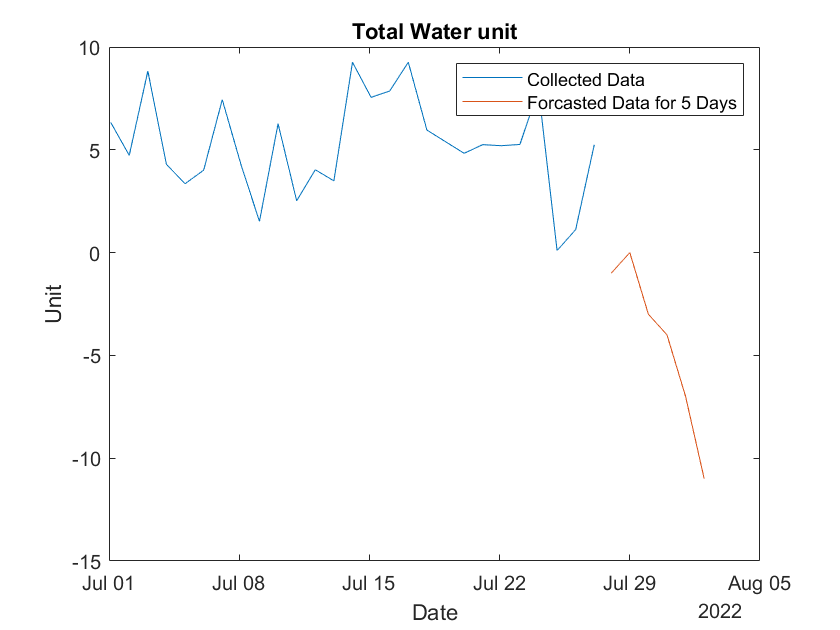

i = 7

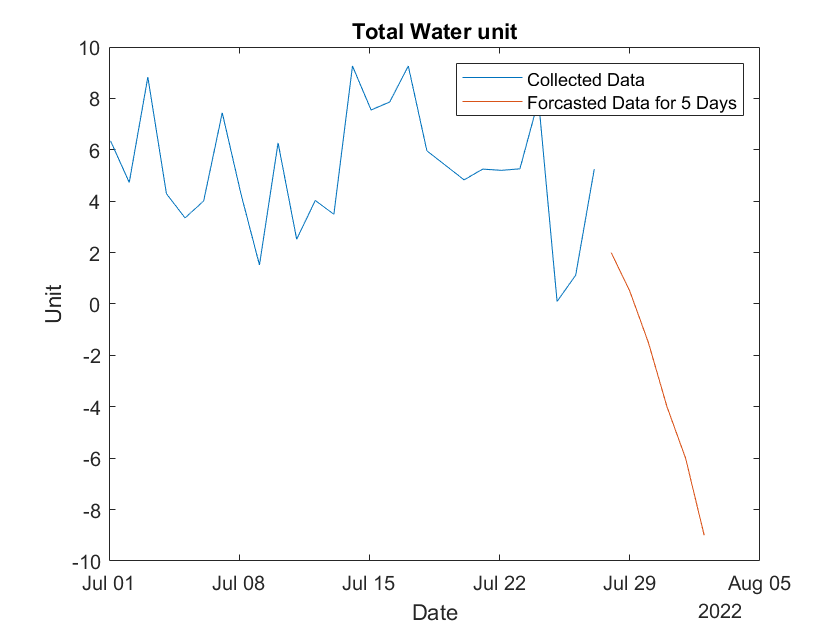

i = 8

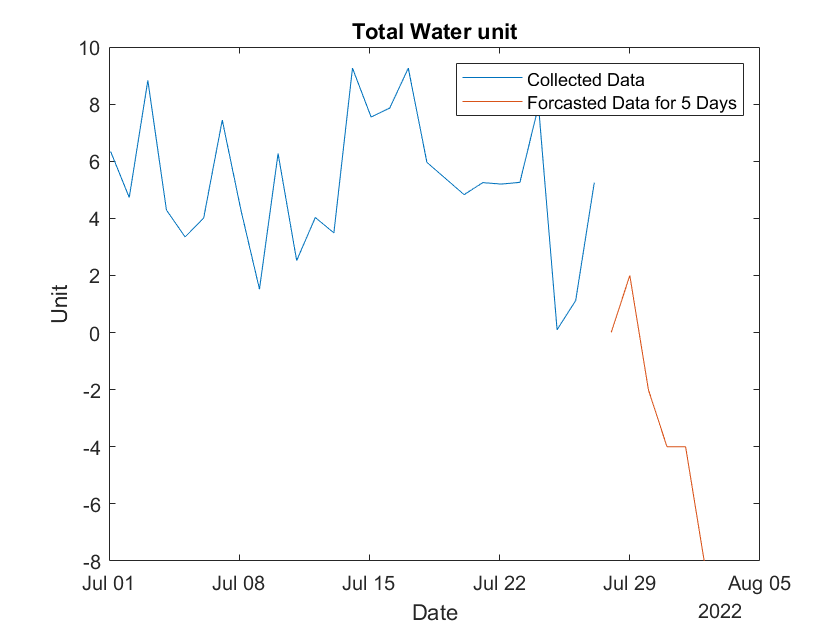

i = 9

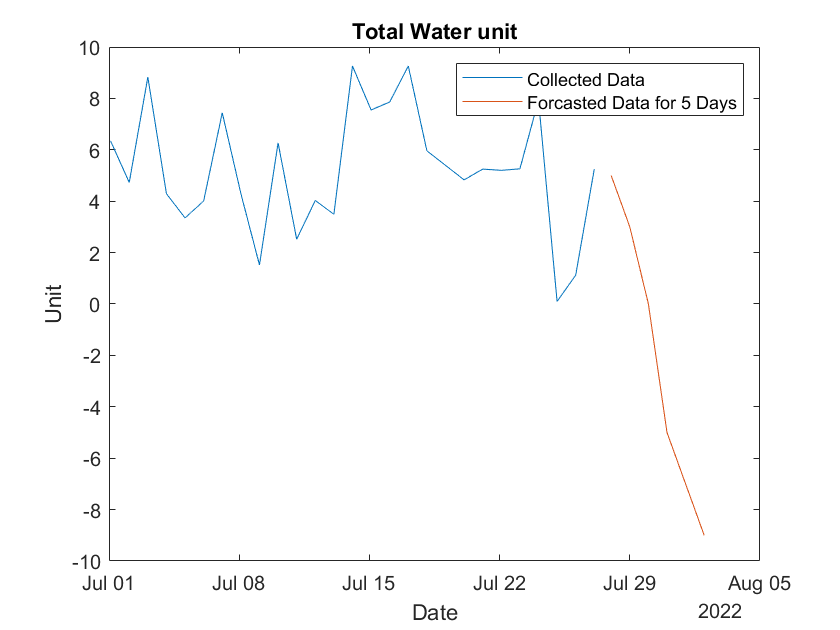

i = 10

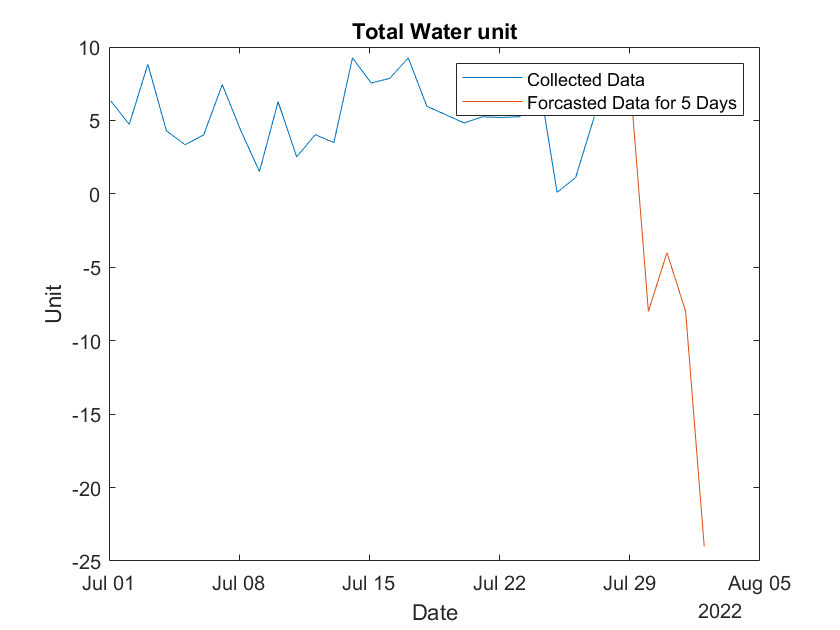

i = 11

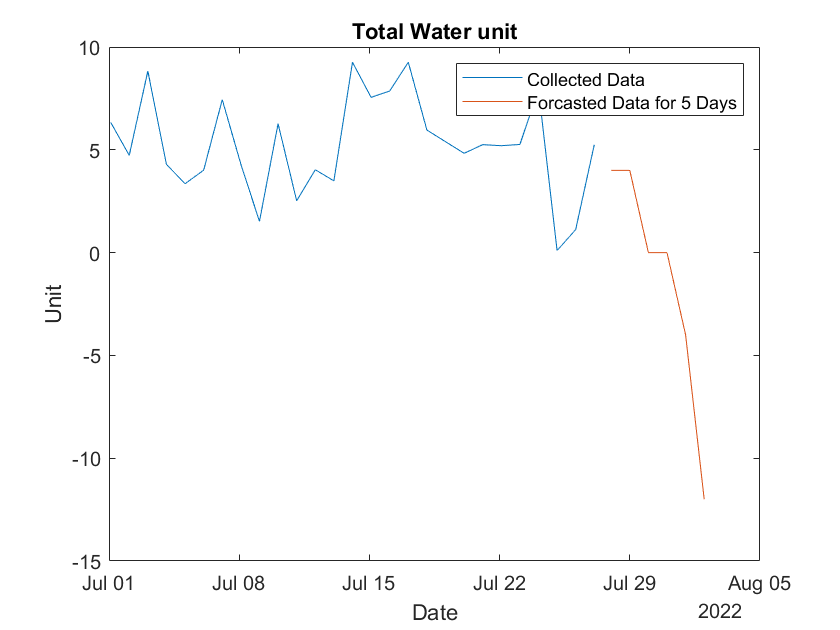

i = 12

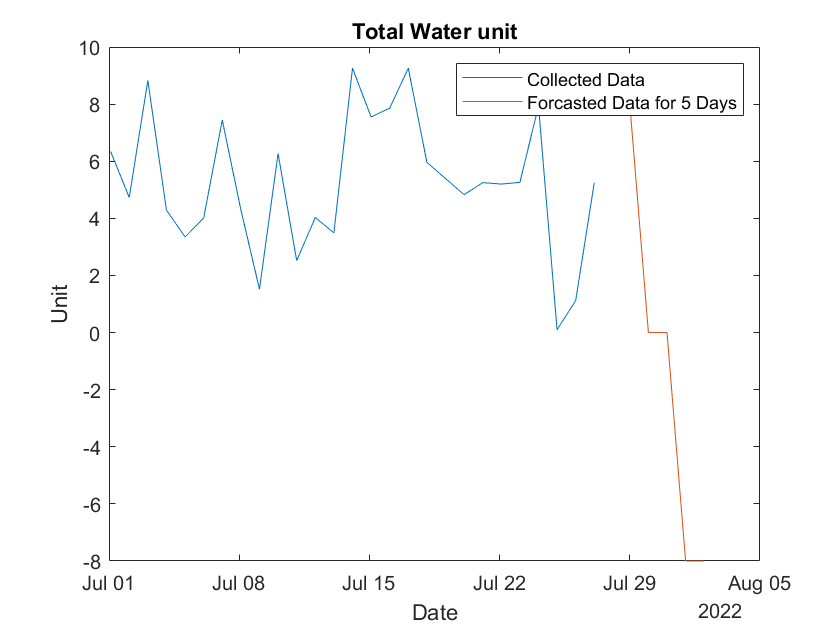

i = 13

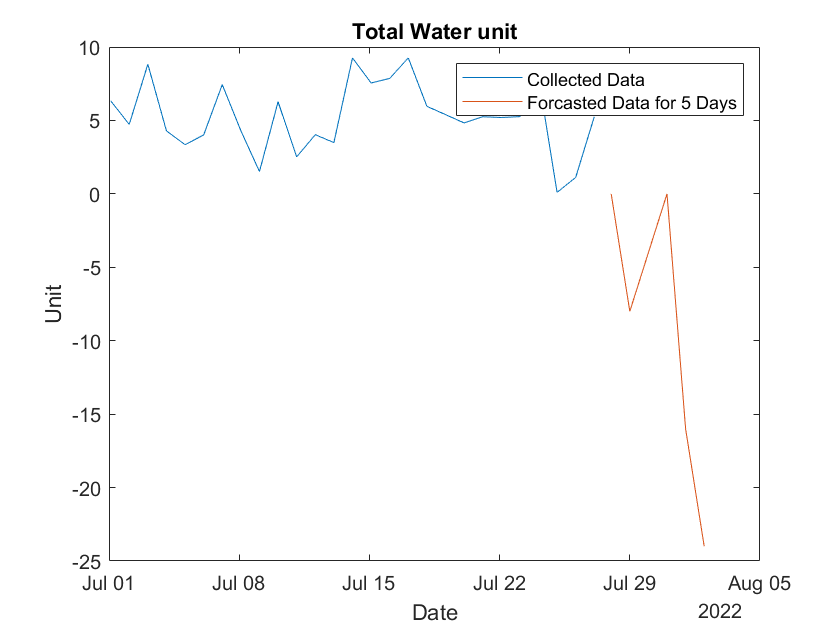

i = 14

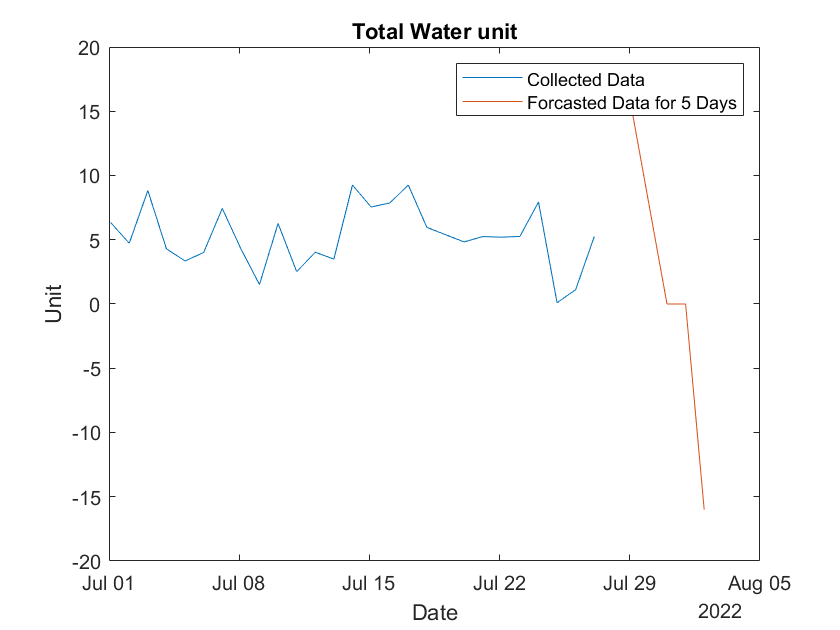

i = 15

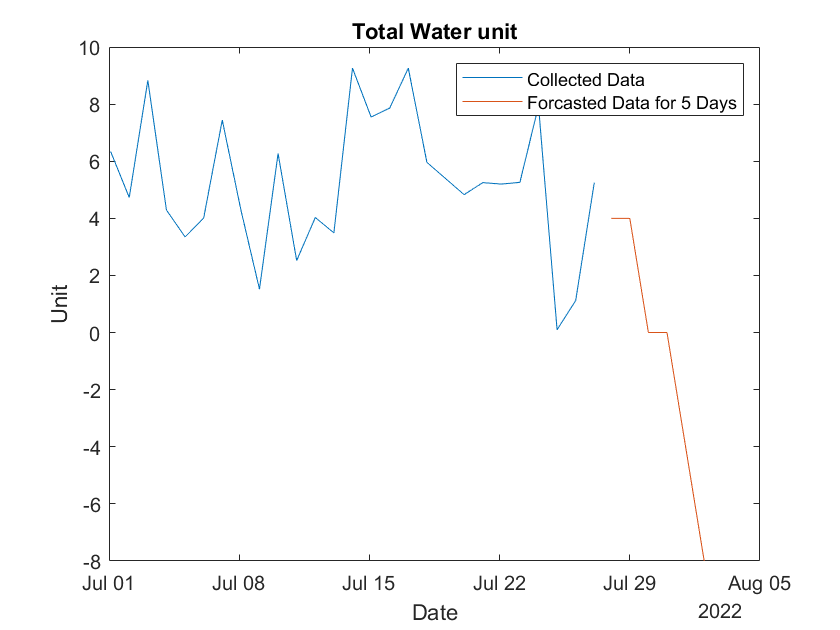

i = 16

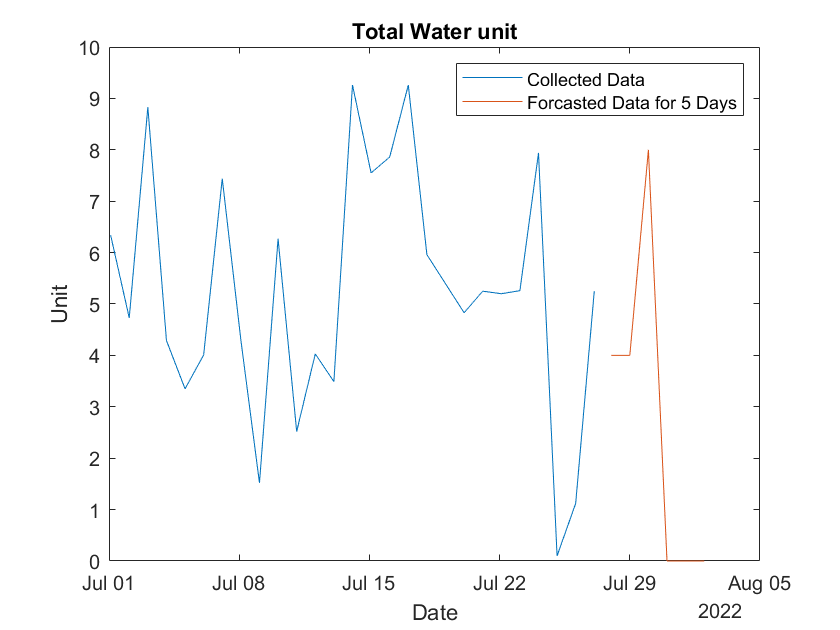

i = 17

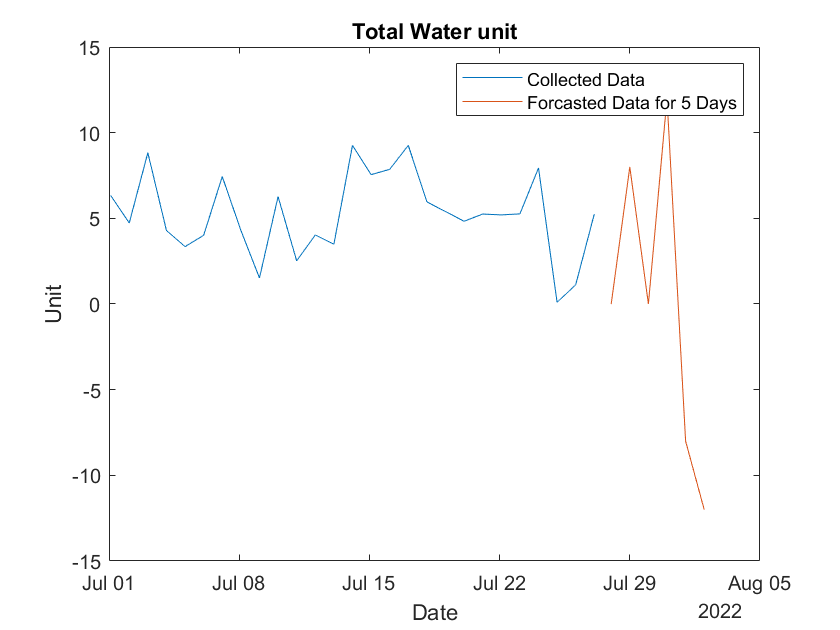

i = 18

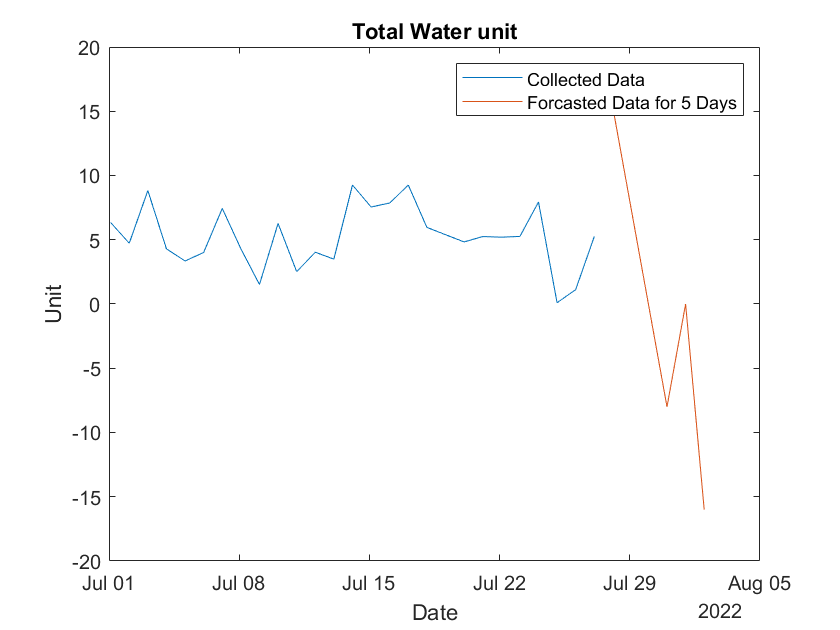

i = 19

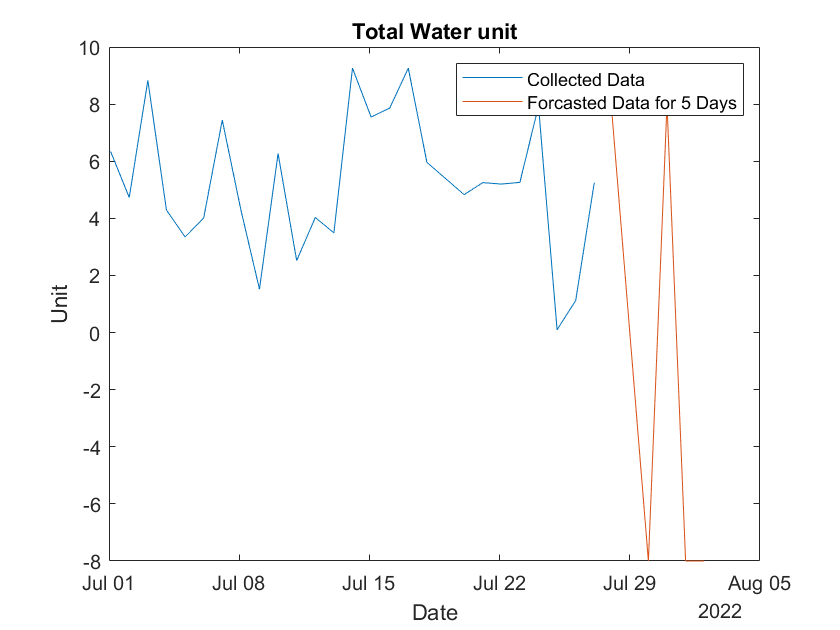

i = 20

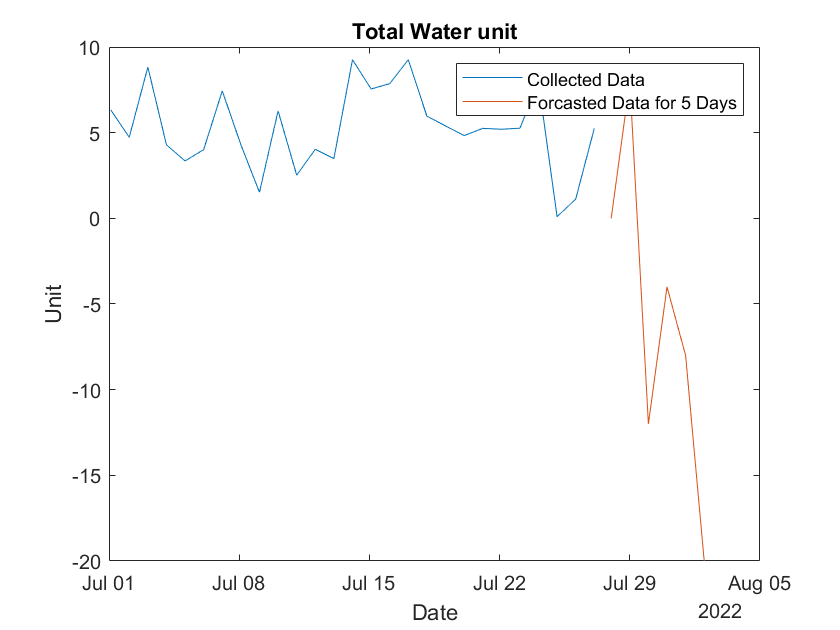

i = 21

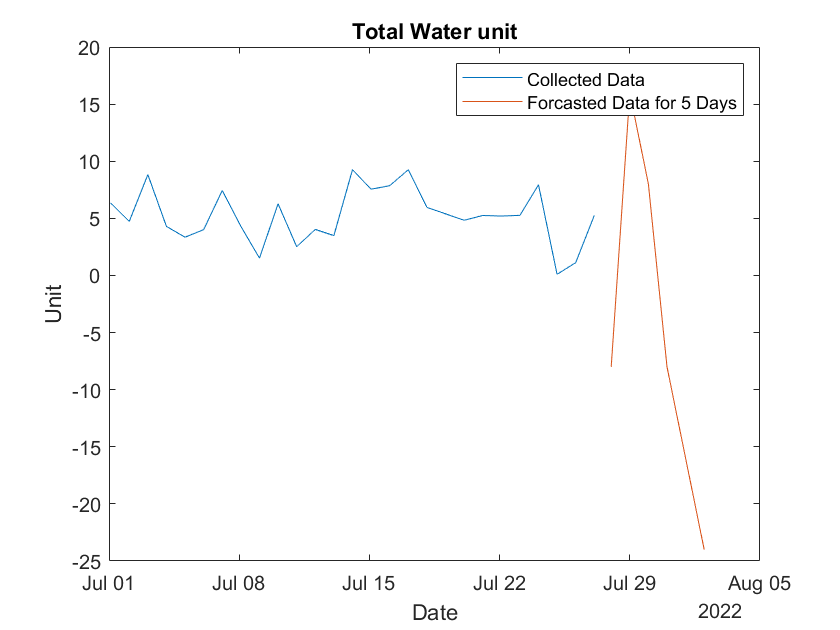

i = 22

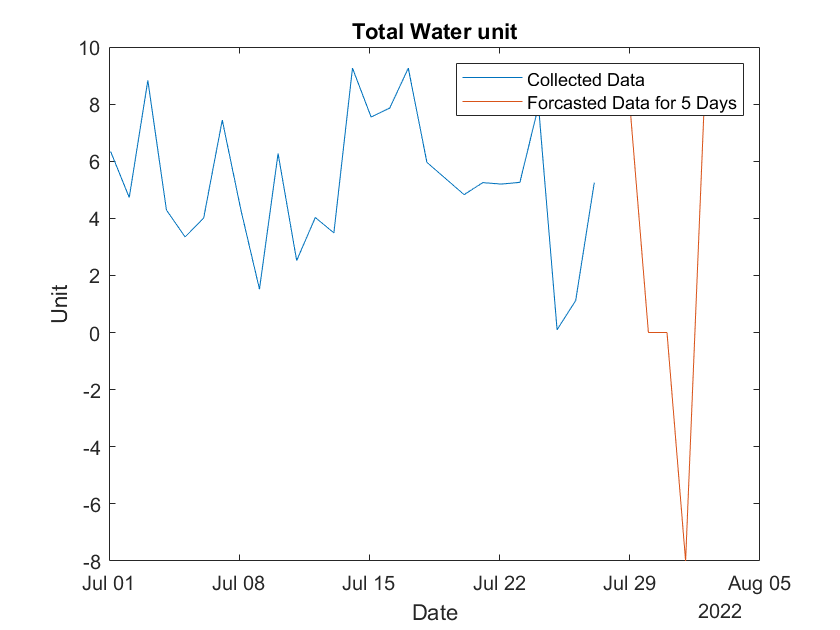

i = 23

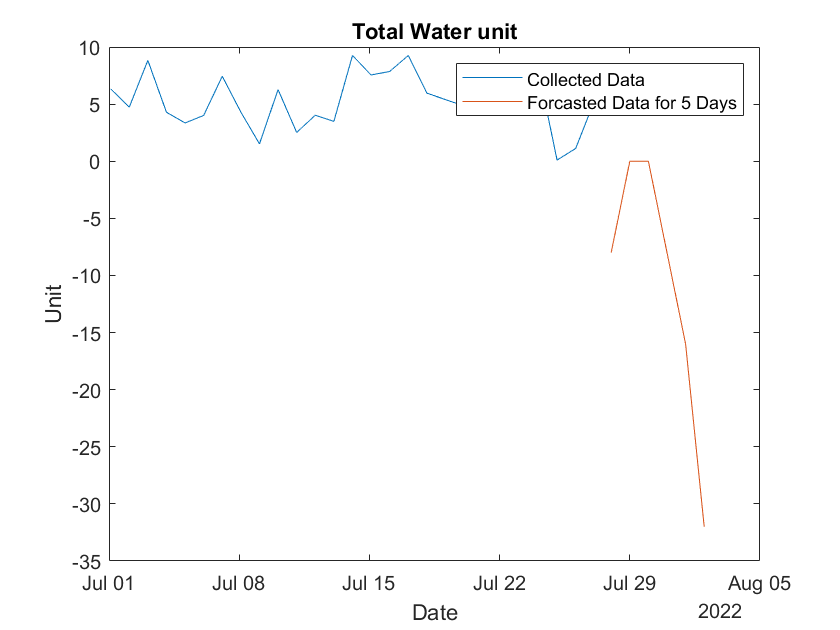

i = 24

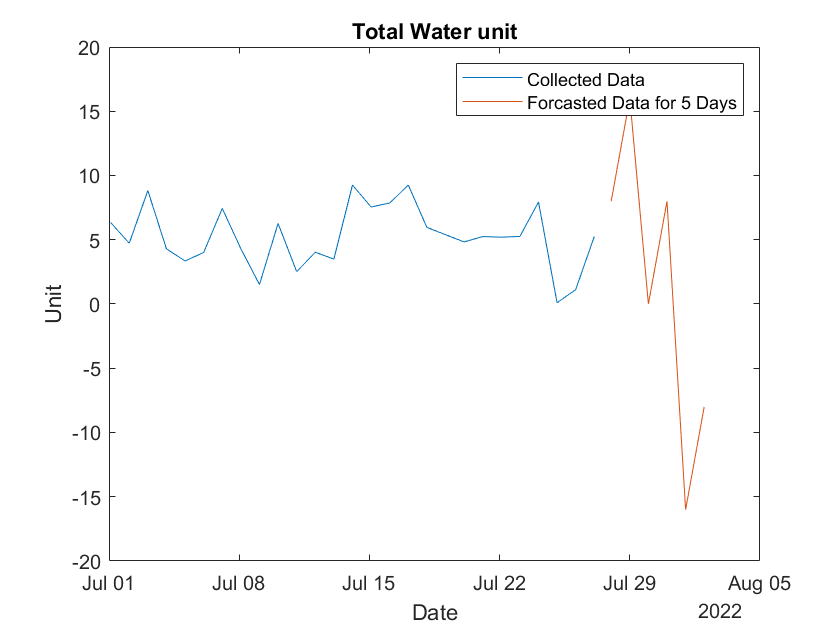

i = 25

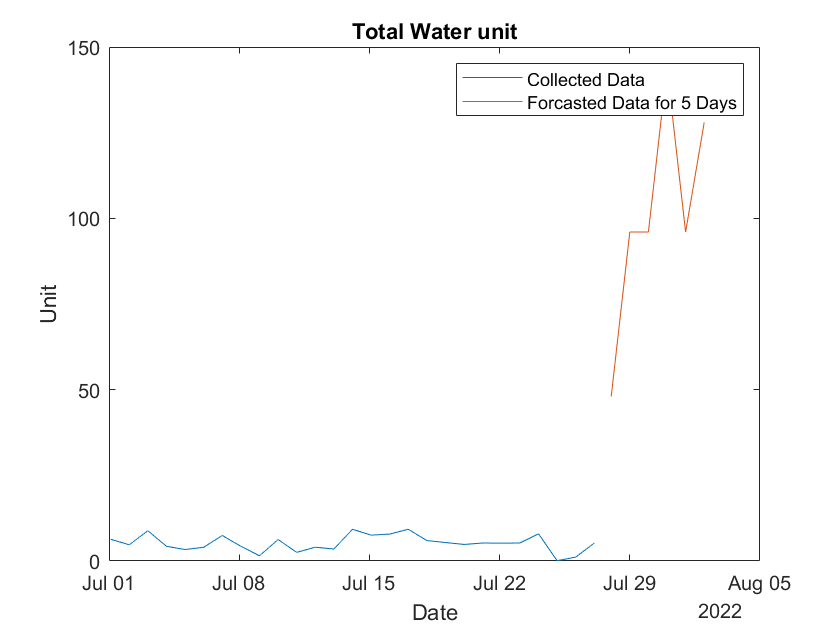

i = 26

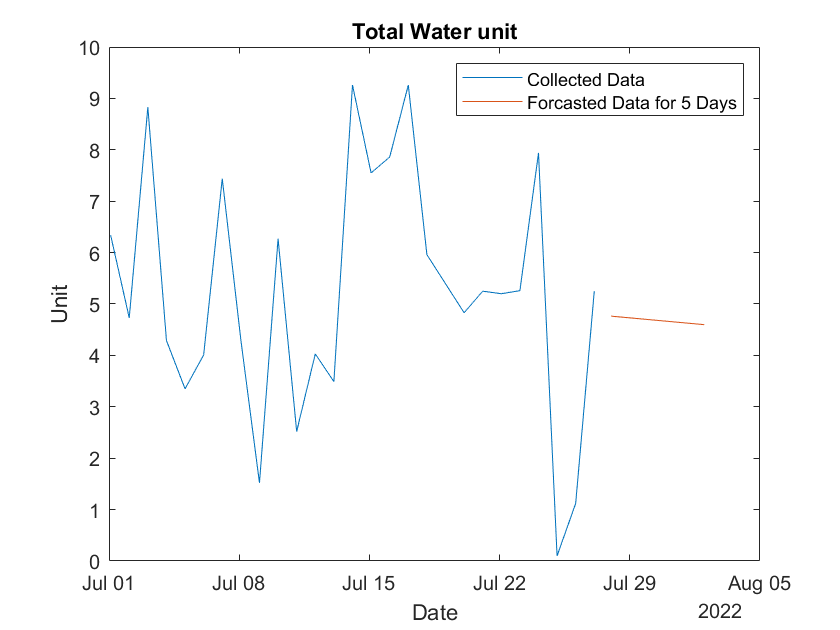

i = 27

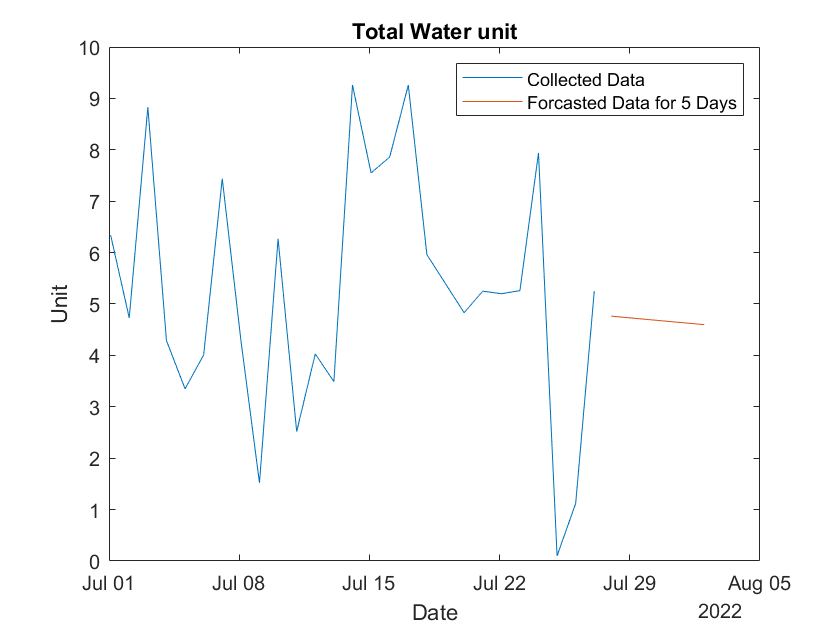

i = 28

i = 29

i = 30

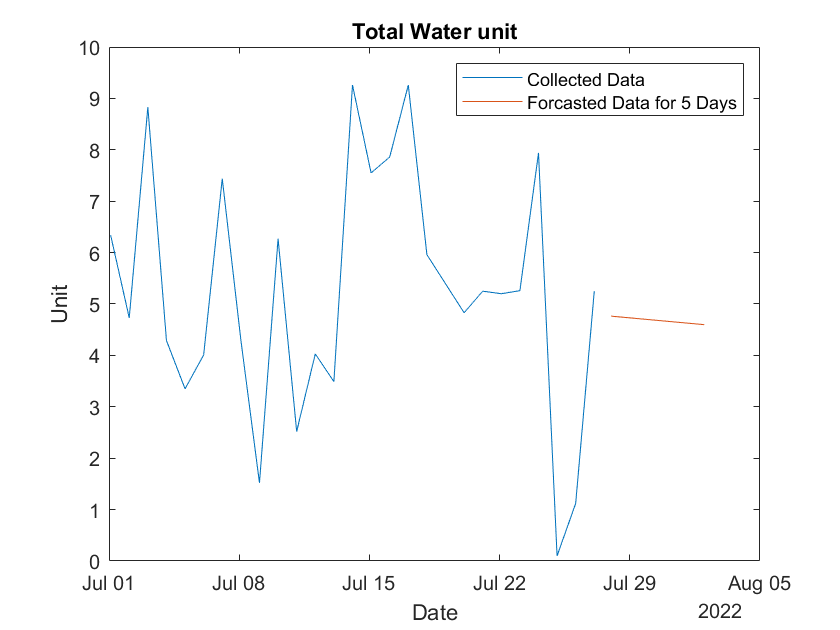

for i=1:30

    x=datenum(time);
    t=Water_Unit';
    X=x';
    i
    p = polyfit(X, t, i);

    future_time=datetime('2022-07-28') + days(00:5) ;
    future = datenum (future_time);
    forecasted_values = polyval(p, future);

    figure
    plot (time, t, '-')
    hold on
    plot (future_time, forecasted_values)
    hold off
    title ('Total Water unit')
    ylabel('Unit')
    xlabel( 'Date')
    legend('Collected Data','Forcasted Data for 5 Days')
    
end